Consider the confound of medication.

Percentage: ratio of medication percentage between sites

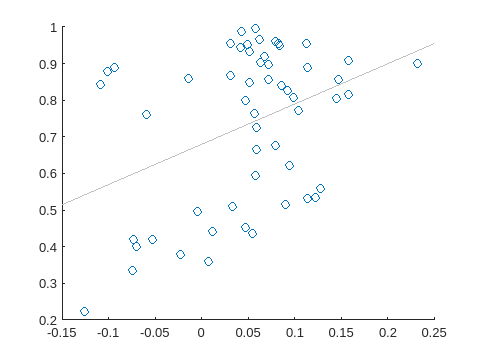

BD


                     Percentage
                     __________

    spearman corr       0.2912 
    p                 0.098509 



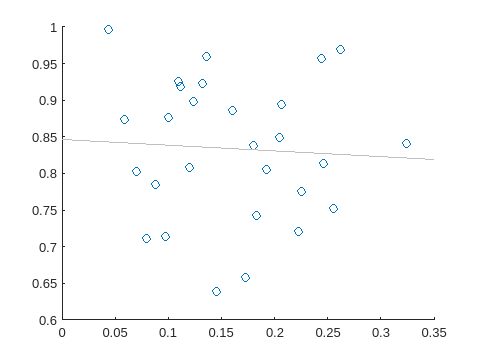

SCA


                     Percentage
                     __________

    spearman corr    -0.031199 
    p                  0.45124 



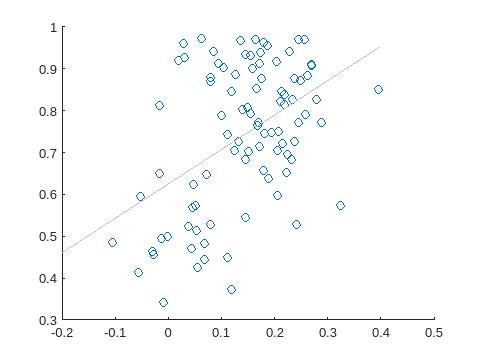

SCZ


                     Percentage
                     __________

    spearman corr         0.37 
    p                 0.041875 



ASD


MDD


AD


% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag',  'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to treatment similarity between sites
    [varTable{iDiag} medRatio{iDiag} nSite{iDiag}]= cor_var_treatment(metadata, diagnosisString(iDiag), corDiag{iDiag},siteList{iDiag}, iter, type);
% Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.


% Save results to a .mat file
save('output/confound_treatment.mat','varTable','medRatio','nSite')